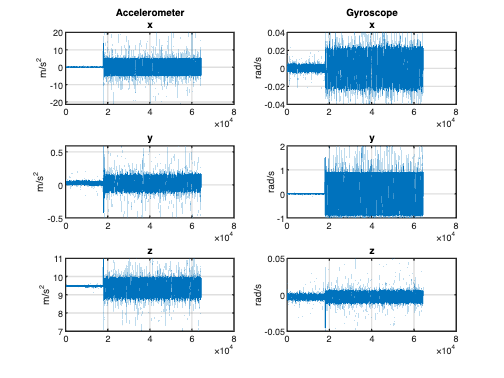

clear all;
close all;
clc;


set(0,'defaultaxeslinewidth',1.5);
set(0,'defaultlinelinewidth',1.5);
set(0,'DefaultAxesFontSize', 12);

%% import recorded data
opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [15, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15"];
opts.SelectedVariableNames = ["VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "string", "string", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9"], "EmptyFieldRule", "auto");

% Import the data
Test1 = readtable("20220202_MTi-G-710_SyncTest.txt", opts);
clear opts;
Test1 = table2array(Test1);

% plot signal to control 

figure('Name','accelerometer and gyroscope')
subplot(3,2,1)
plot(Test1(:,1))
title(["Accelerometer","x"])
ylabel('m/s^2')
grid on
subplot(3,2,2)
plot(Test1(:,4))
title(["Gyroscope","x"])
ylabel('rad/s')
grid on
subplot(3,2,3)
plot(Test1(:,2))
ylabel('m/s^2')
title('y')
grid on
subplot(3,2,4)
plot(Test1(:,5))
title('y')
ylabel('rad/s')
grid on
subplot(3,2,5)
plot(Test1(:,3))
title('z')
ylabel('m/s^2')
grid on
subplot(3,2,6)
plot(Test1(:,6))
title('z')
ylabel('rad/s')
grid on